# Average Velocity Plots

clearvars -except fm fmv dualfm dualfmv

Color code - pinks = Pachon cave fish

Blues = Surface fish

%% colors
%Pinks
salmon = [255/255, 140/255, 105/255];
Modred = [193/255, 90/255, 99/255];
skin = [194/255, 150/255, 130/255];
Magenta = [187/255, 86/255, 149/255];
pinks = [salmon, Modred, skin, Magenta];
%Blues
BlueSky = [98/255, 122/255, 157/255];
Flowerblue = [133/255, 128/255, 177/255];
Bluegreen = [130/255, 189/255, 170/255];
Cyan = [8/255, 133/255, 161/255];

# Worm fed

#### LD - Pachon

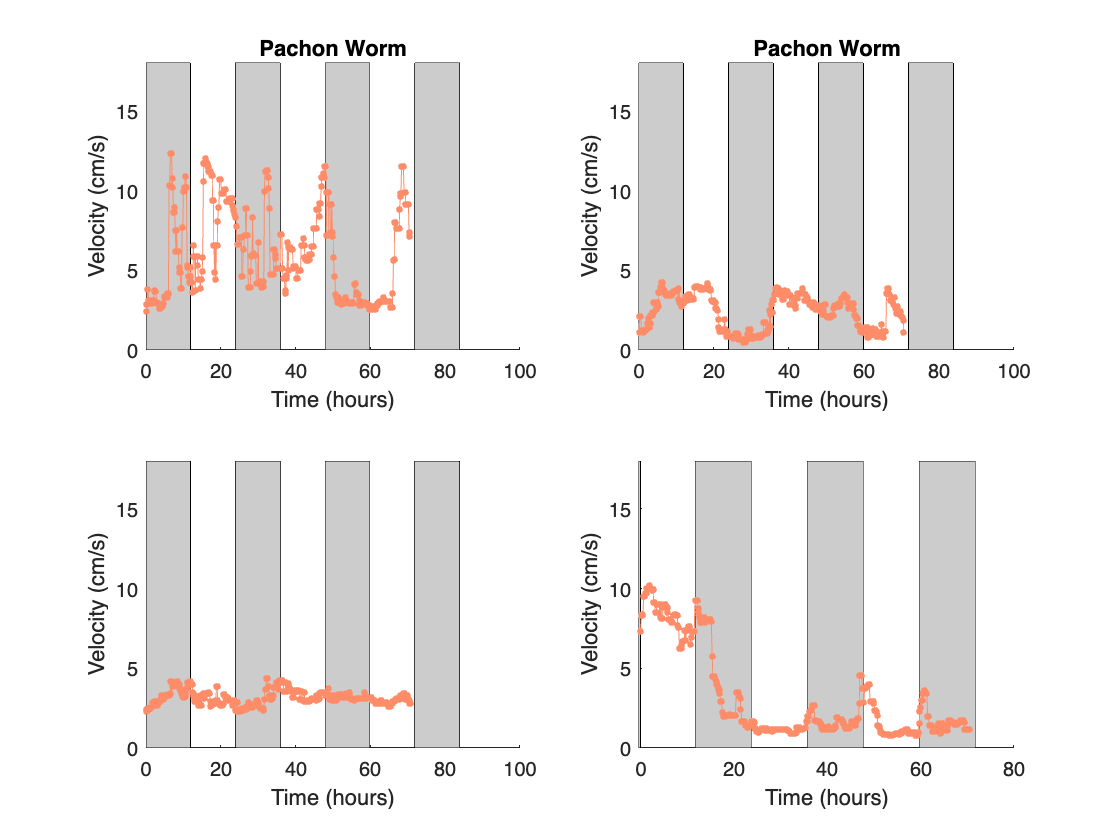

%indices of fmv data structure to plot
%need to adjust times for 34 and 35 to start at 4pm
fmvidx = [1 2 3];
%tim of 1 = 16.13
%lighttimes of 1 = 28 (starts at 16, removed to make plotting easier)
clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Pachon Worm"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end
subplot(224); hold on; ylim([0,18]); %add single fish from different trial
j = 42;
        % created LD lines
        tmplightimes = fmv(j).timfo.lighttimes-fmv(j).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
       plot([fmv(j).timfo.timcont]-[fmv(j).timfo.timcont(1)], (medfilt1([fmv(j).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 

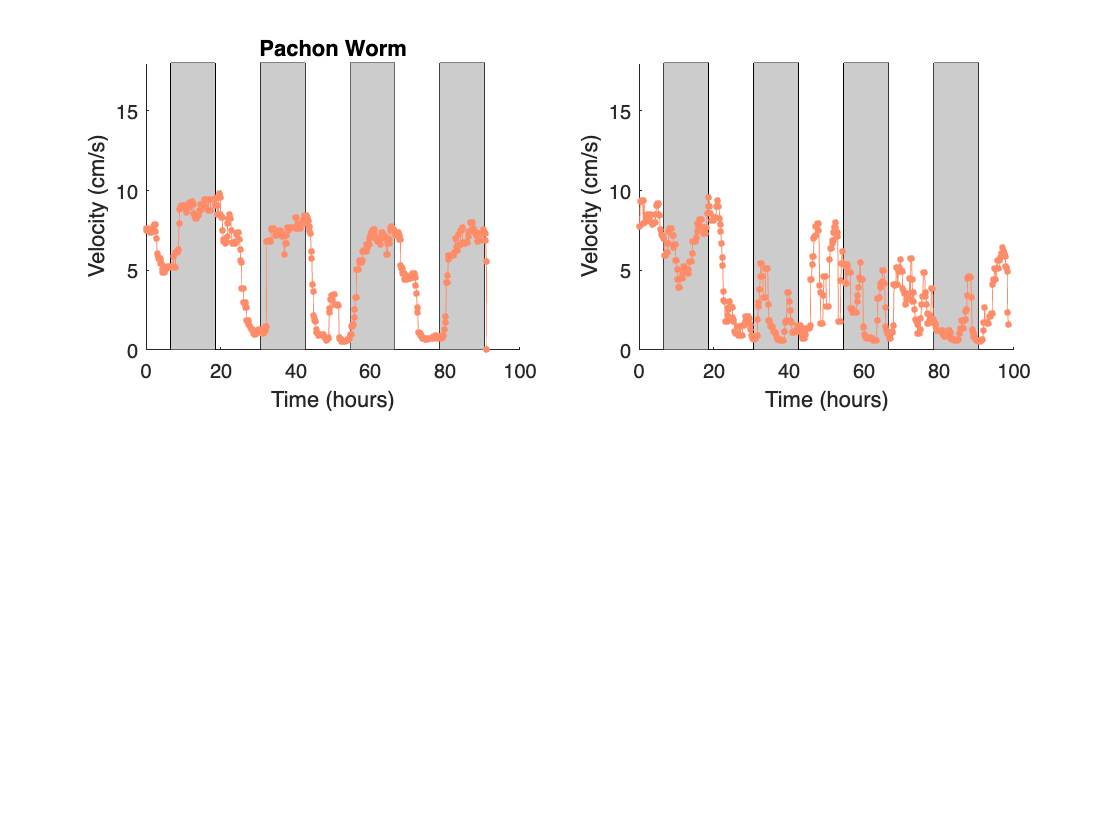


%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [34, 35];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Pachon Worm"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH LIGHT
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

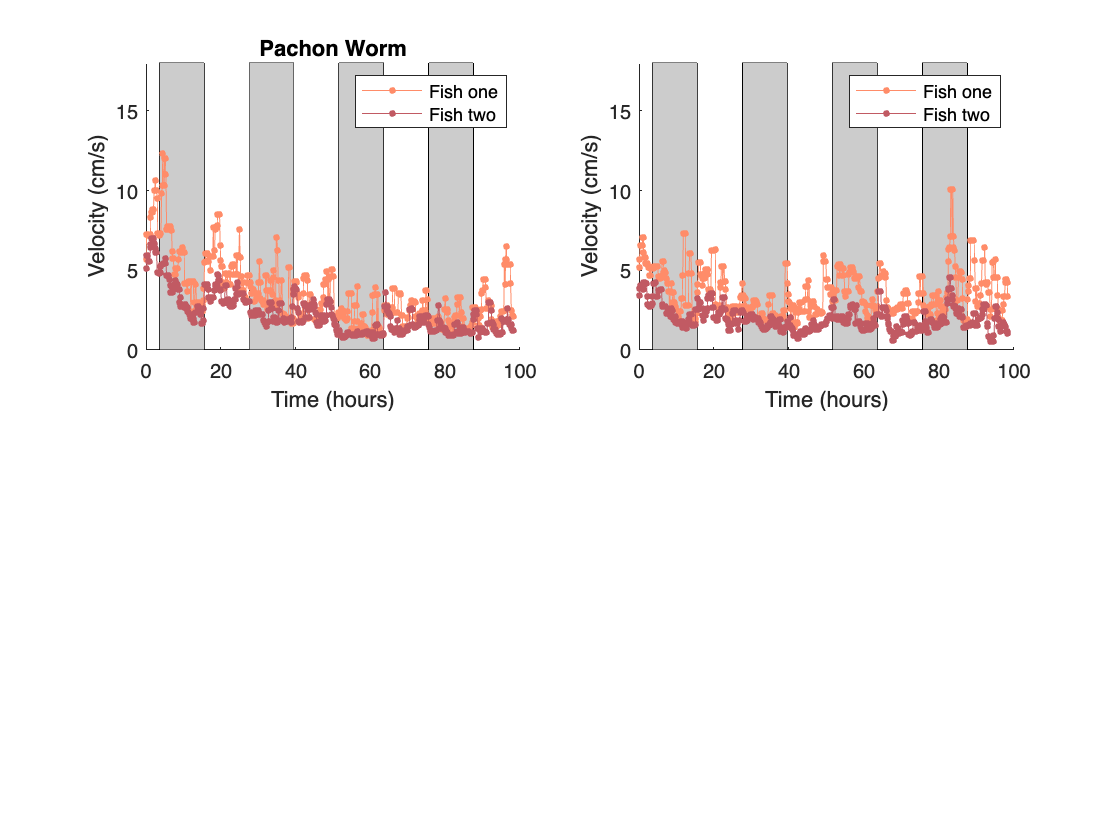

%indices of fmv data structure to plot
clear fmvidx;
clear k;
dualfmvidx = [6 , 7];

clf; 
%loop through idicies to generate plots
for k = 1:length(dualfmvidx)
    figure(1); title("Pachon Worm"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = dualfmv(dualfmvidx(k)).timfo.lighttimes-dualfmv(dualfmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH LIGHT
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
   
       p1 = plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.onevel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       p2 =  plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.twovel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', Modred);

    
      legend([p1 p2], 'Fish one', 'Fish two');

  
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### DD - Pachon

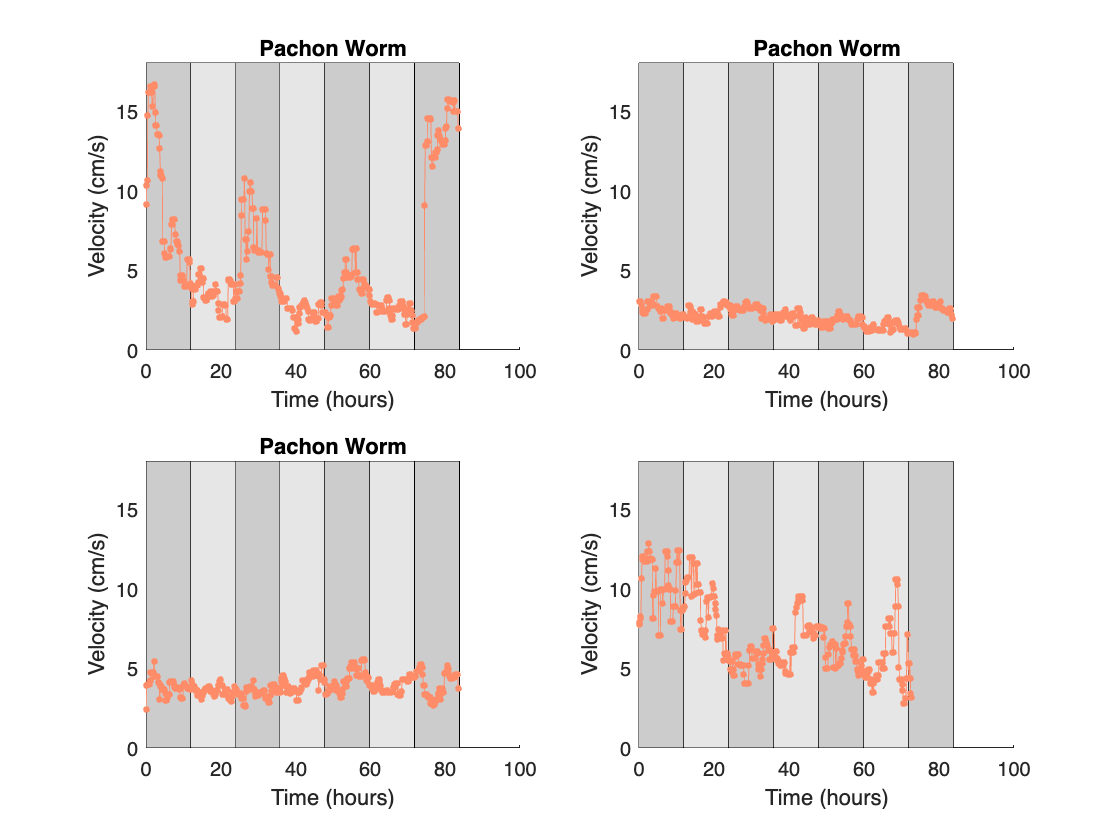

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [5 6 7 39];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(2); title("Pachon Worm"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %ALWAYS DARK
       %ALL DARK
       greylight = 0.9;
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[greylight greylight greylight])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [greylight greylight greylight])
      % fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [greylight greylight greylight])

       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

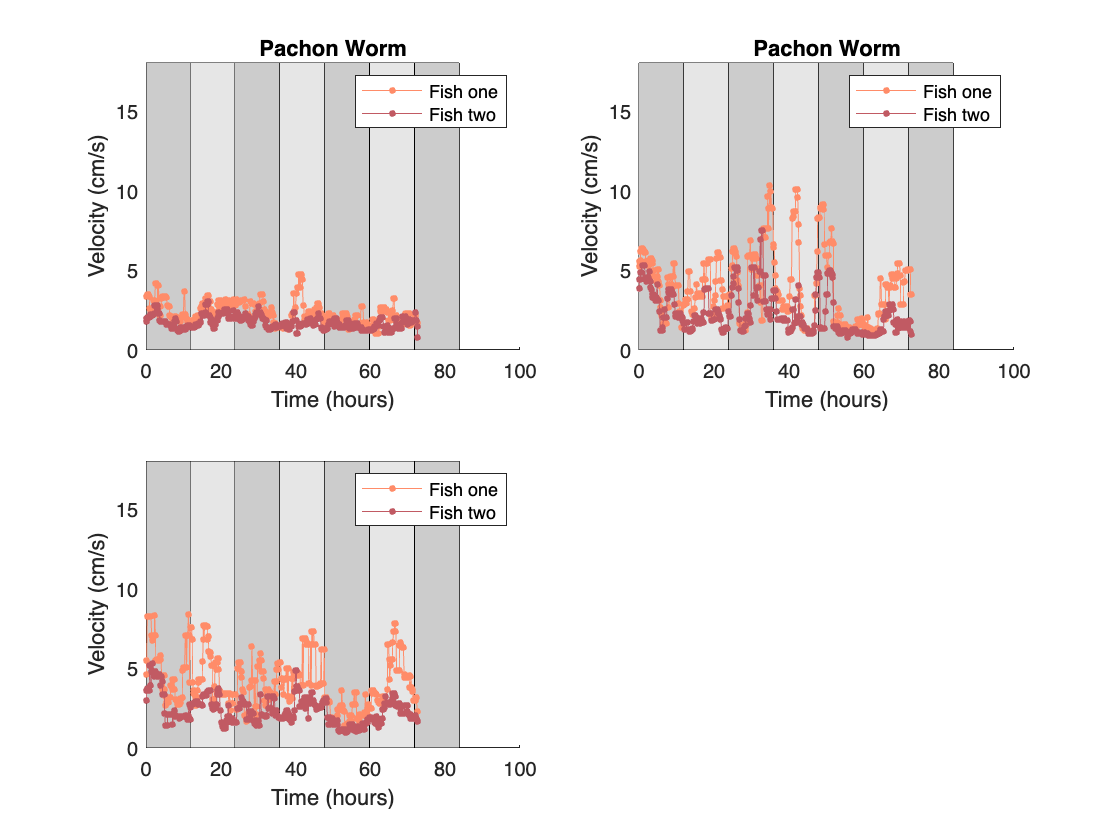

%indices of fmv data structure to plot
clear fmvidx;
clear k;
dualfmvidx = [9 10 11];

clf; 
%loop through idicies to generate plots
for k = 1:length(dualfmvidx)
    figure(1); title("Pachon Worm"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = dualfmv(dualfmvidx(k)).timfo.lighttimes-dualfmv(dualfmvidx(k)).timfo.timcont(1)';
        %create fill lines
         %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %ALWAYS DARK
       %ALL DARK
       greylight = 0.9;
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[greylight greylight greylight])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [greylight greylight greylight])
       %plot
   
       p1 = plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.onevel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       p2 =  plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.twovel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', Modred);

    
      legend([p1 p2], 'Fish one', 'Fish two');

  
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

## Worm fed

#### LD - Surface

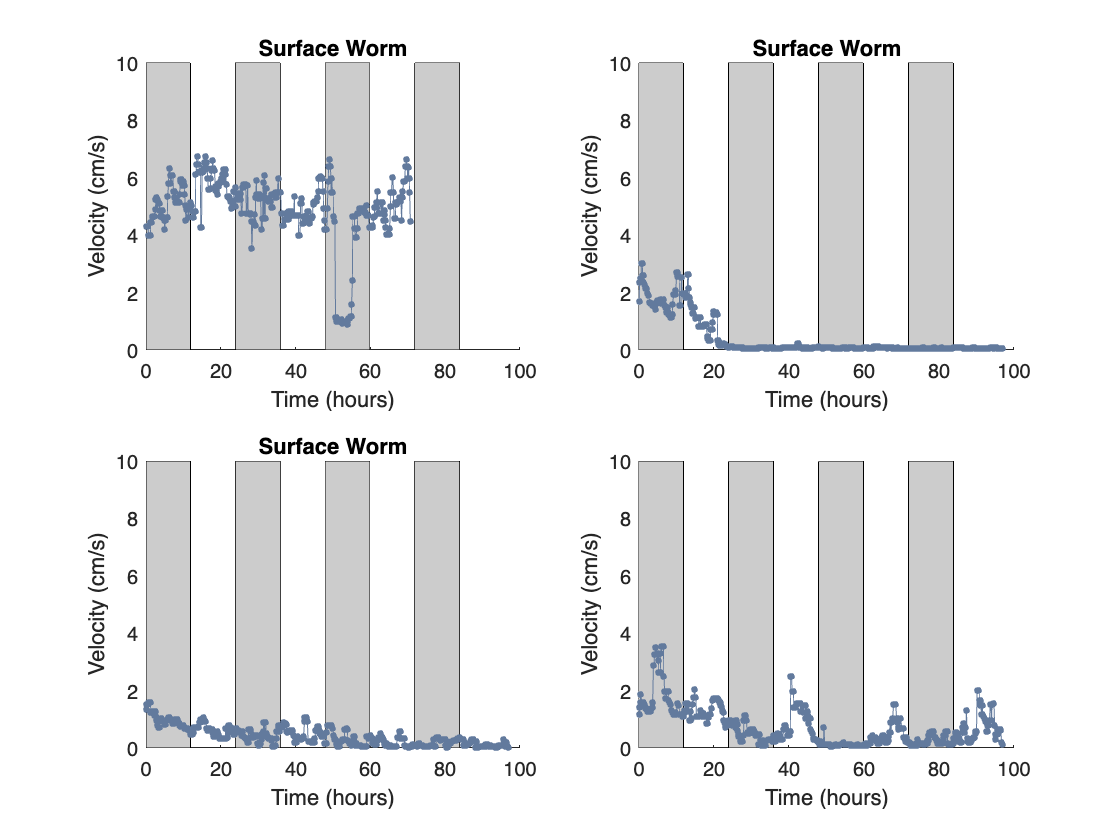

%indices of fmv data structure to plot
%important that we start at 4:08 pm not 4 pm... need to work on time vector plotting
clear fmvidx;
clear k;
fmvidx = [4 36 37 38];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Surface Worm"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,10]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 10 10 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 10 10 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 10 10 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 10 10 0], [0.8 0.8 0.8])
       
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', BlueSky);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### DD - Surface

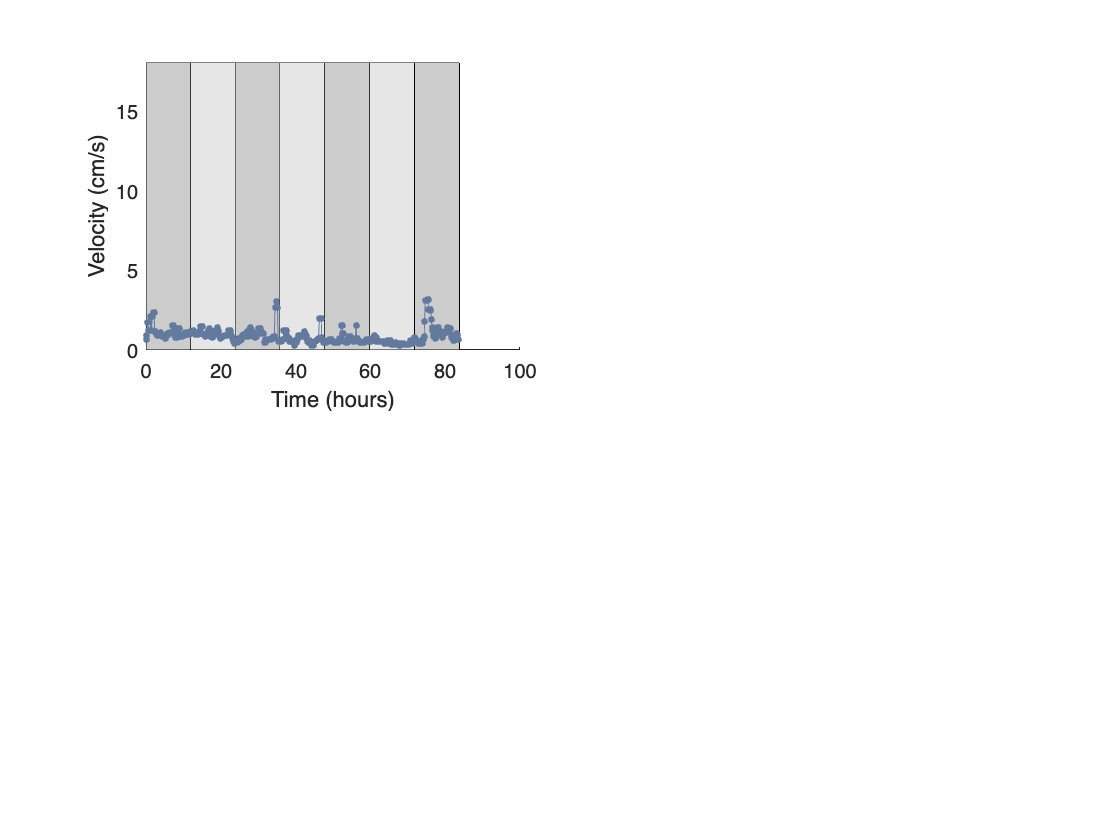

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [8];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Surface Worm"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %ALWAYS DARK
       %ALL DARK
       greylight = 0.9;
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[greylight greylight greylight])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [greylight greylight greylight])
       %fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [greylight greylight greylight])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', BlueSky);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

# Dayflakes

#### LD - Pachon

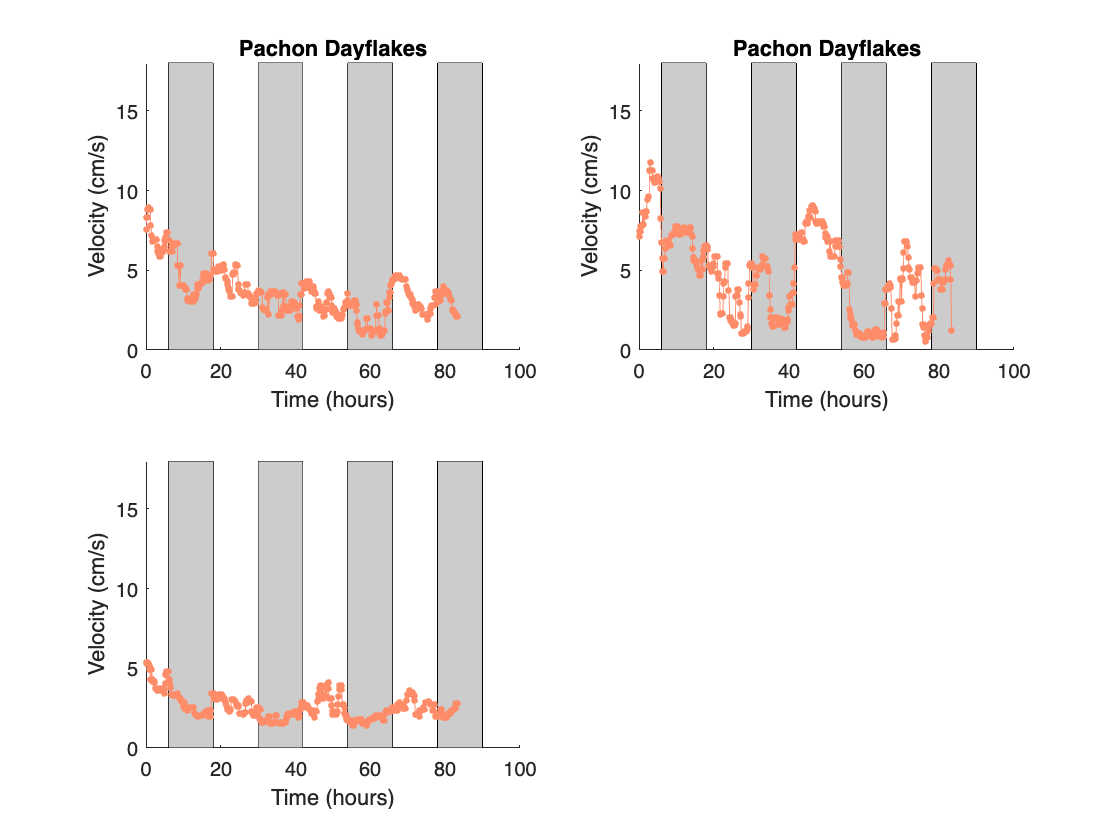

%indices of fmv data structure to plot
clear fmvidx;
fmvidx = [27 28 29];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Pachon Dayflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
         %STARTS WITH LIGHT
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0],  [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0],  [0.8 0.8 0.8])
       fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0],  [0.8 0.8 0.8])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

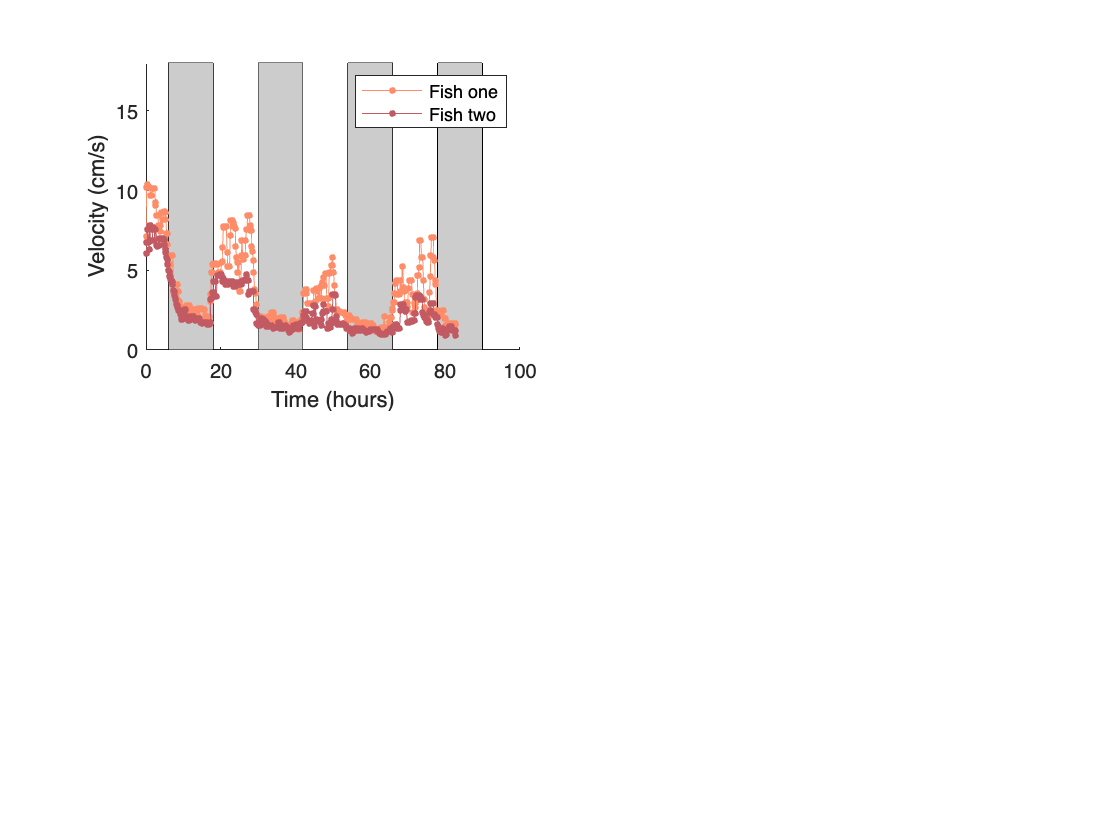

%indices of fmv data structure to plot
clear fmvidx;
clear k;
dualfmvidx = [1];

clf; 
%loop through idicies to generate plots
for k = 1:length(dualfmvidx)
    figure(1); title("Pachon Dayflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = dualfmv(dualfmvidx(k)).timfo.lighttimes-dualfmv(dualfmvidx(k)).timfo.timcont(1)';
        %create fill lines
         %create fill lines
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0],  [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0],  [0.8 0.8 0.8])
       fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0],  [0.8 0.8 0.8])
       %plot
   
       p1 = plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.onevel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       p2 =  plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.twovel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', Modred);

    
      legend([p1 p2], 'Fish one', 'Fish two');

  
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### DD - Pachon

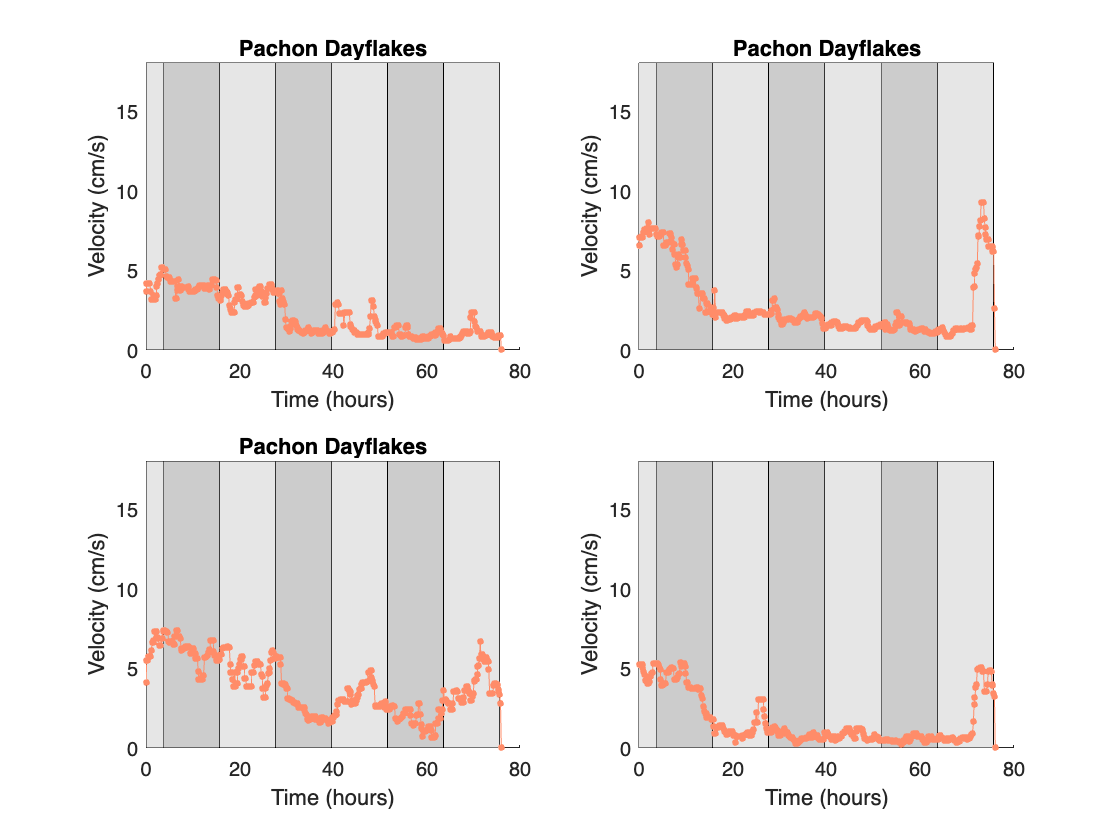

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [17 18 19 20];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(2); title("Pachon Dayflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
          %STARTS WITH LIGHT
        greydark = 0.8; greylight = 0.9;
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [greylight greylight greylight])
       %ALWAYS DARK
       %ALL DARK
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [0.8 0.8 0.8])
      % fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [greylight greylight greylight])

       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### LD - Surface

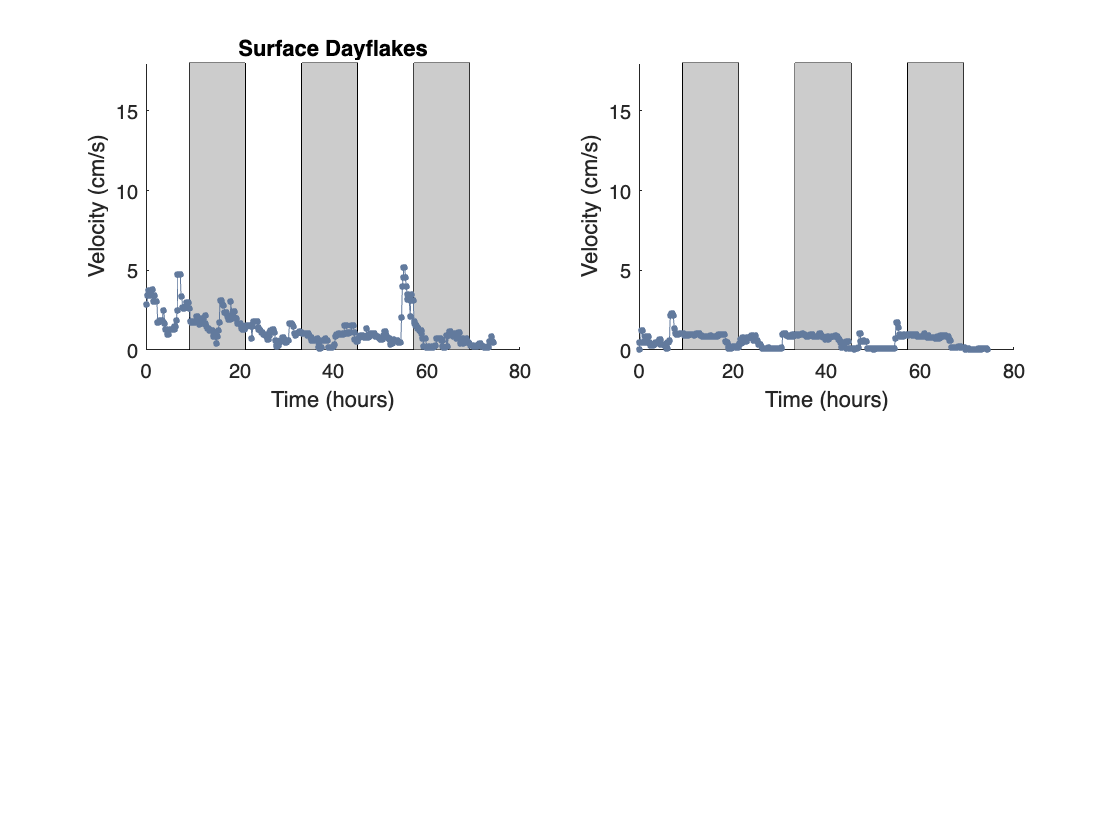

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [32 33];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Surface Dayflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
       
         %STARTS WITH LIGHT
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0],  [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0],  [0.8 0.8 0.8])
      % fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0],  [0.8 0.8 0.8])
       
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', BlueSky);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

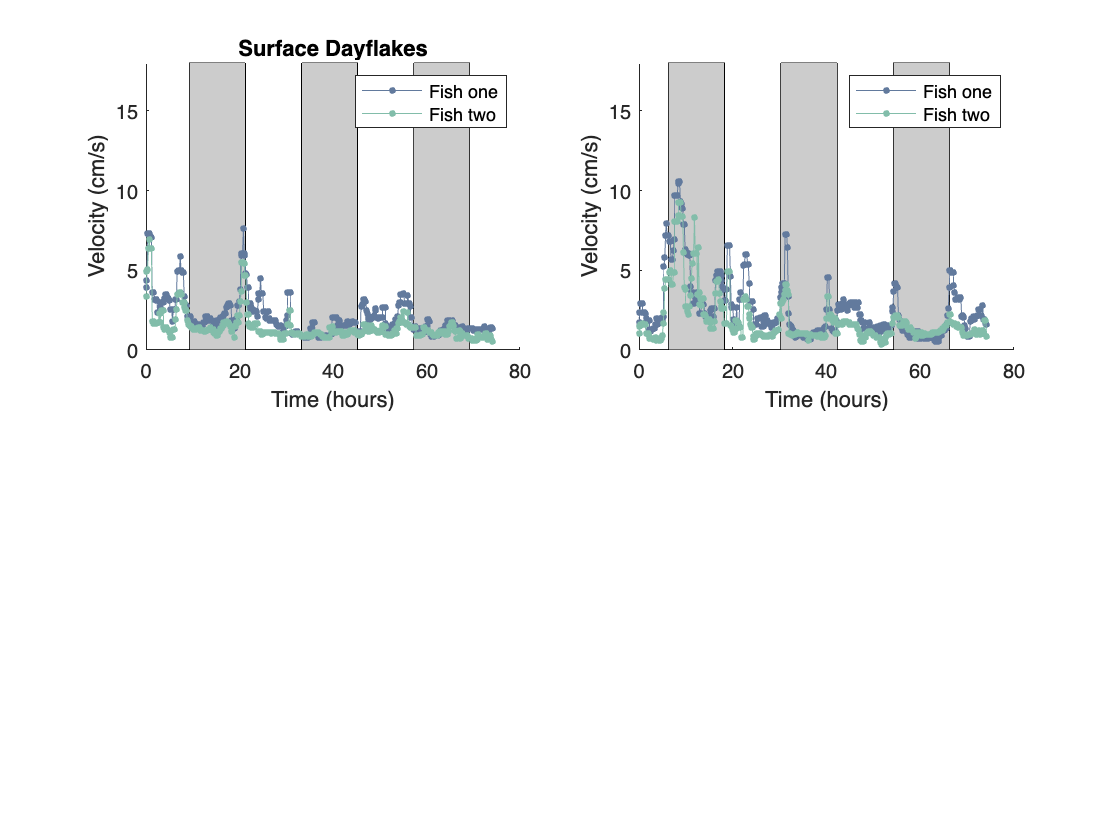

%indices of fmv data structure to plot
clear fmvidx;
clear k;
dualfmvidx = [4 5];

clf; 
%loop through idicies to generate plots
for k = 1:length(dualfmvidx)
    figure(1); title("Surface Dayflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = dualfmv(dualfmvidx(k)).timfo.lighttimes-dualfmv(dualfmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH LIGHT
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0],  [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0],  [0.8 0.8 0.8])
       %plot
   
       p1 = plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.onevel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', BlueSky);
       p2 =  plot([dualfmv(dualfmvidx(k)).timfo.timcont]-[dualfmv(dualfmvidx(k)).timfo.timcont(1)], (medfilt1([dualfmv(dualfmvidx(k)).ss.twovel], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', Bluegreen);

    
      legend([p1 p2], 'Fish one', 'Fish two');

  
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### DD - Surface

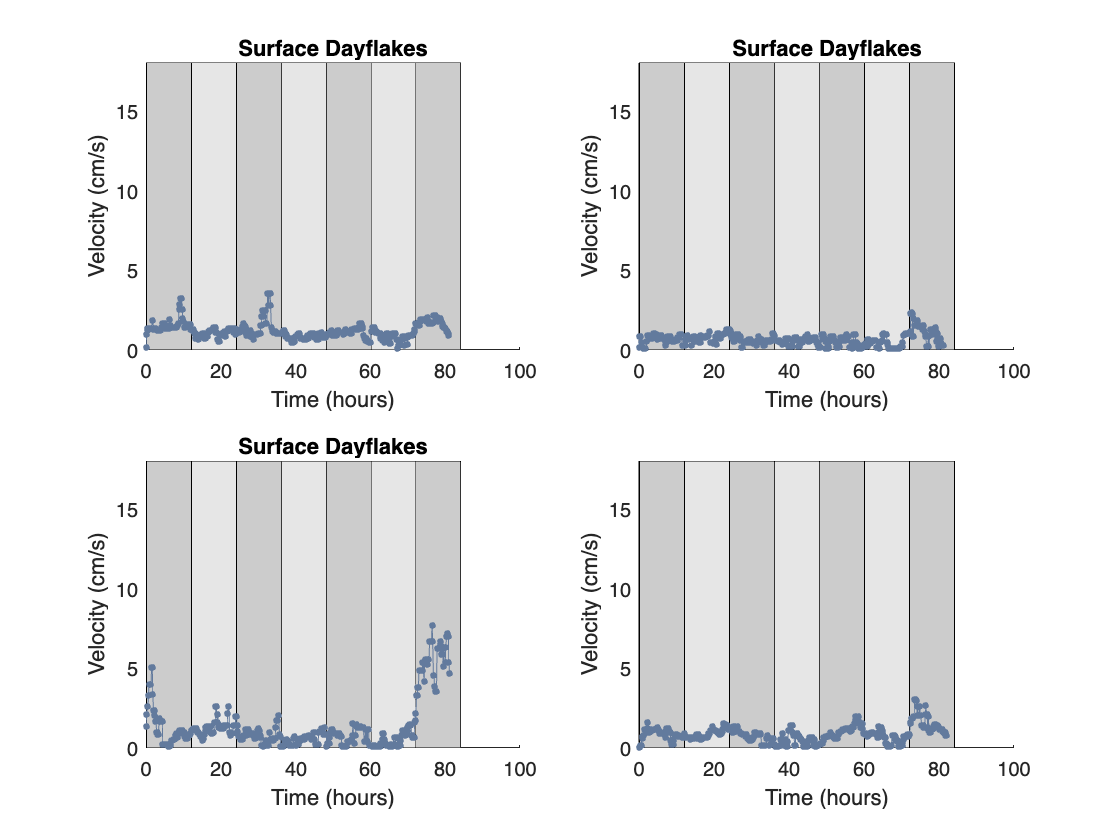

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [9 10 11 12];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Surface Dayflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
         greydark = 0.8; greylight = 0.9;
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [greylight greylight greylight])
       %ALWAYS DARK
       %ALL DARK
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', BlueSky);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

# Nightflakes

#### LD - Pachon

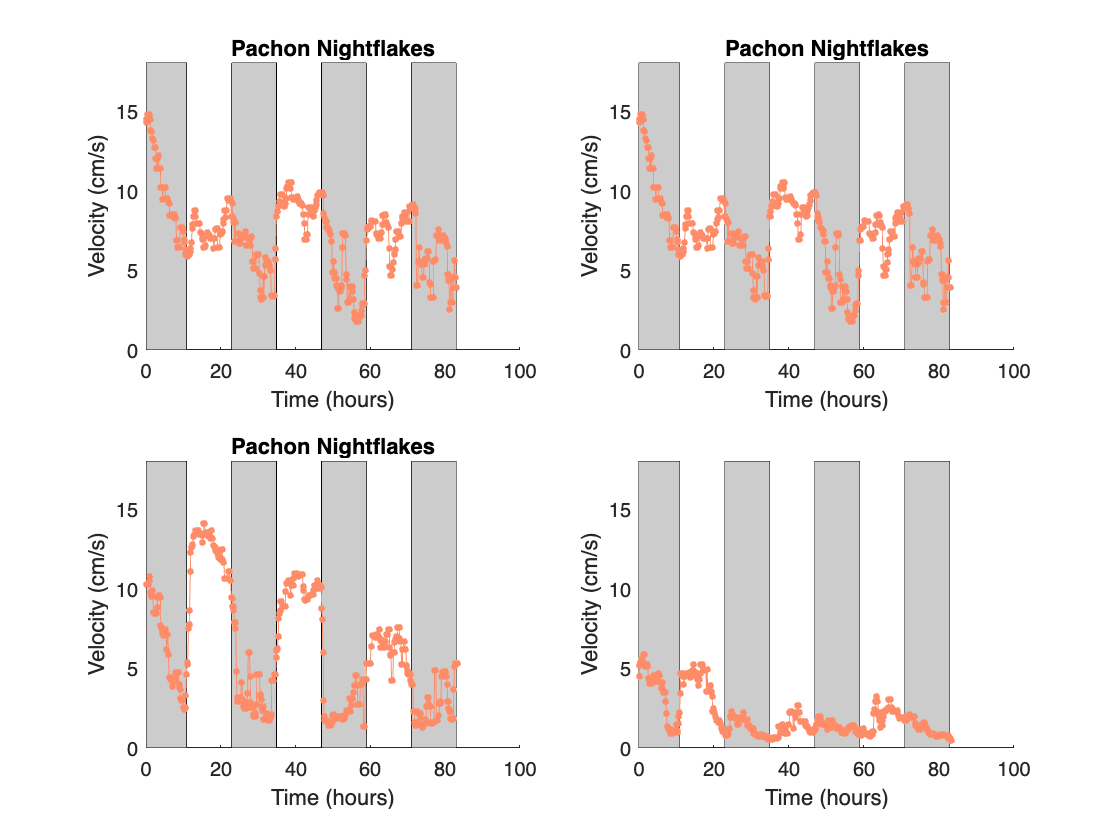

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [22 23 24 25];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Pachon Nightflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### DD - Pachon

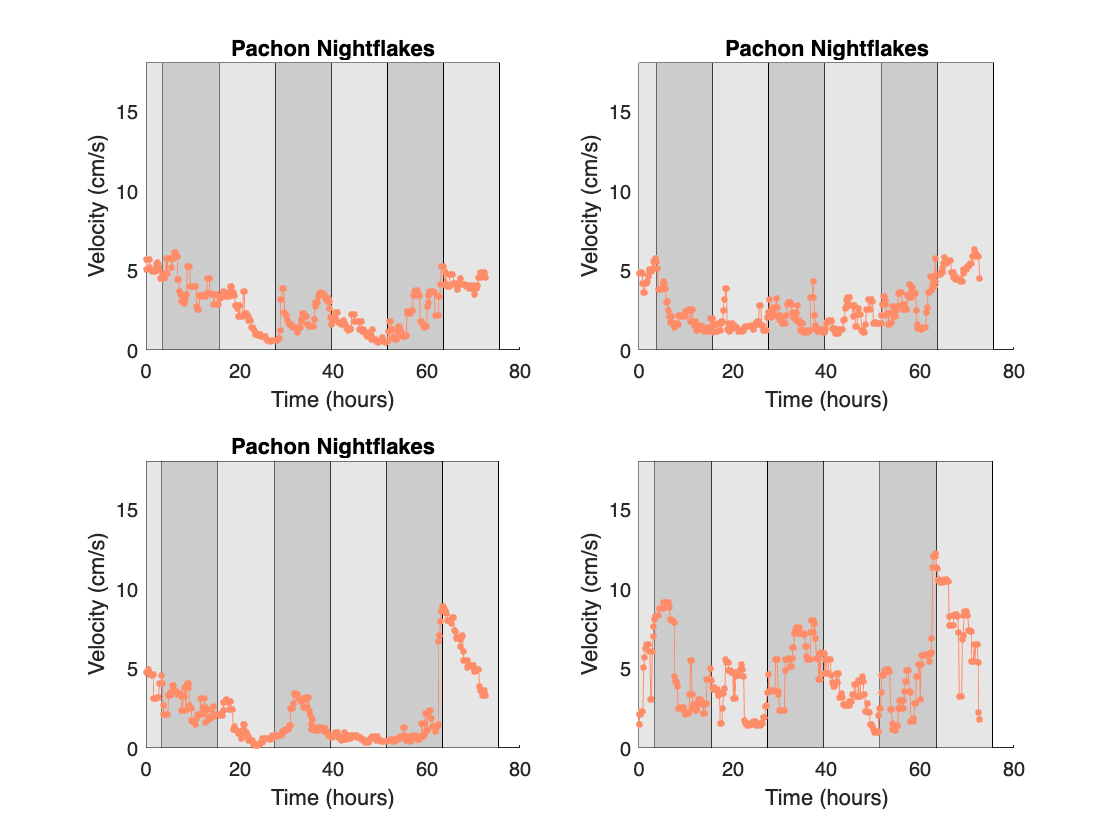

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [13 14 15 16];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(2); title("Pachon Nightflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH LIGHT
        greydark = 0.8; greylight = 0.9;
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [greylight greylight greylight])
       %ALWAYS DARK
       %ALL DARK
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [0.8 0.8 0.8])
      % fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [greylight greylight greylight])

       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

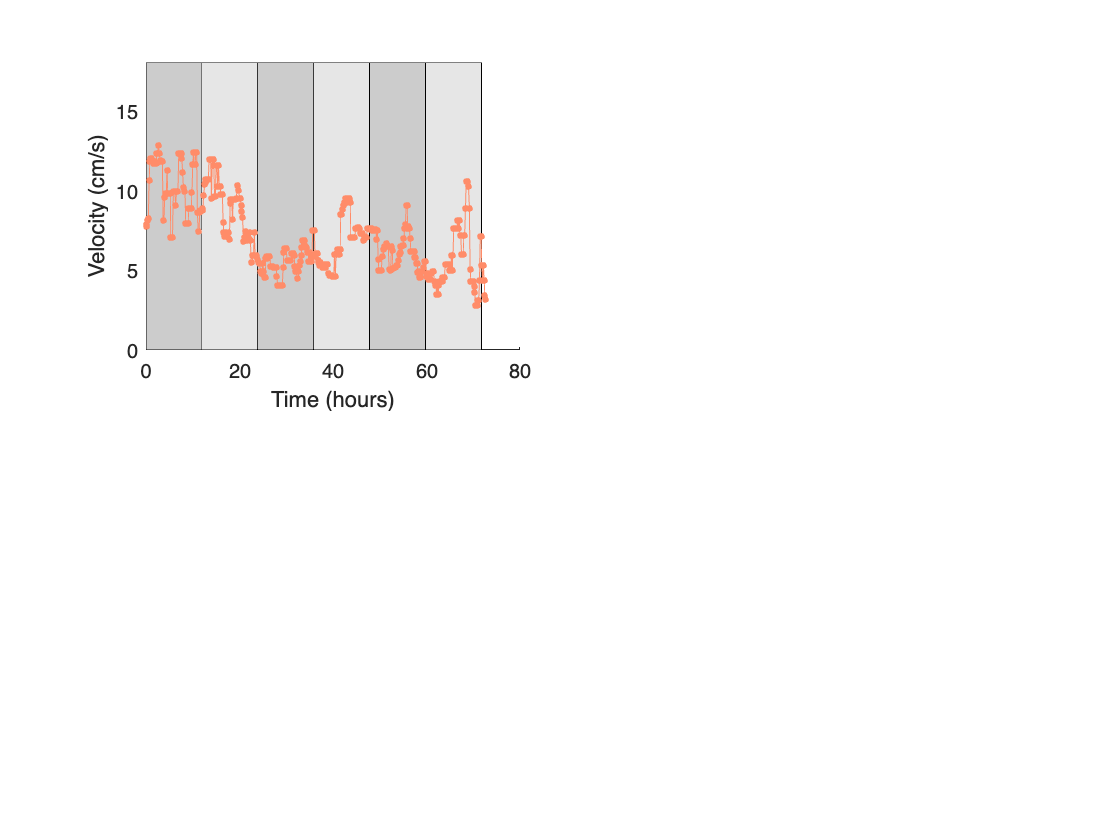

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [39];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Surface Dayflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
         greydark = 0.8; greylight = 0.9;
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
      % fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %ALWAYS DARK
       %ALL DARK
       greylight = 0.9;
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[greylight greylight greylight])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [greylight greylight greylight])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', salmon);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### LD - Surface

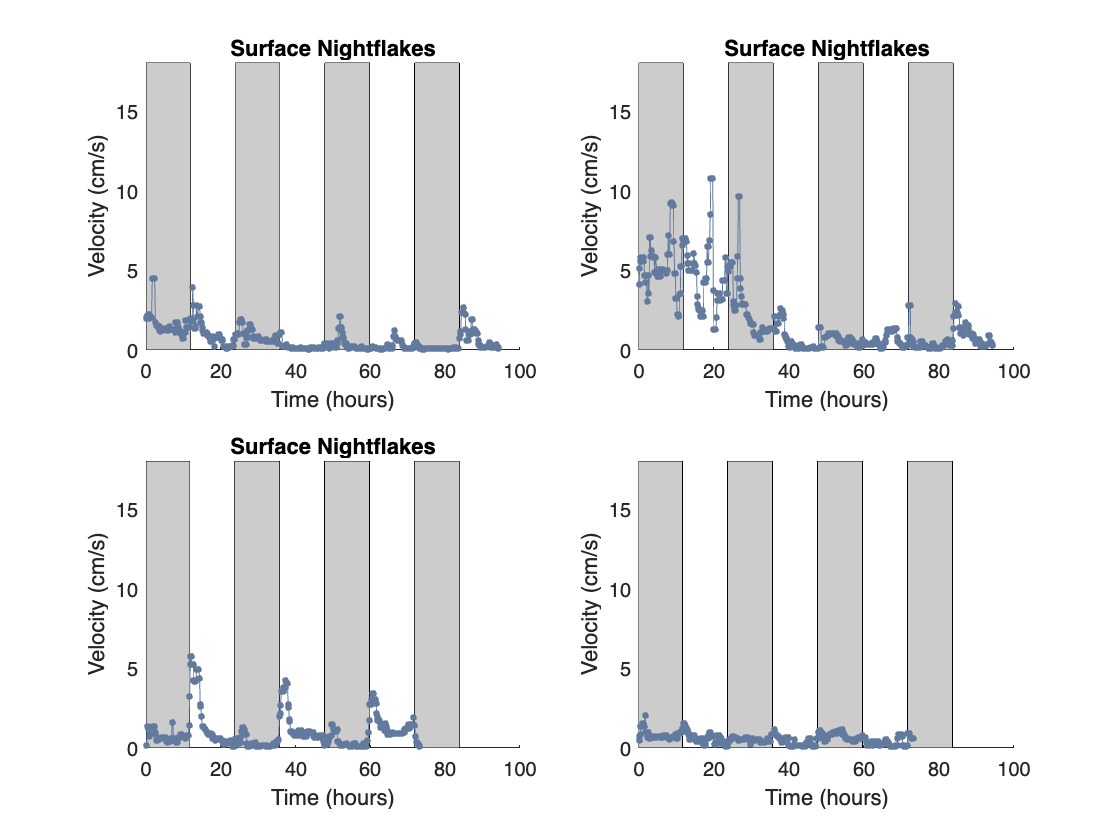

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [30 31 40 41];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Surface Nightflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
        %STARTS WITH DARK
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', BlueSky);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end

#### DD - Surface

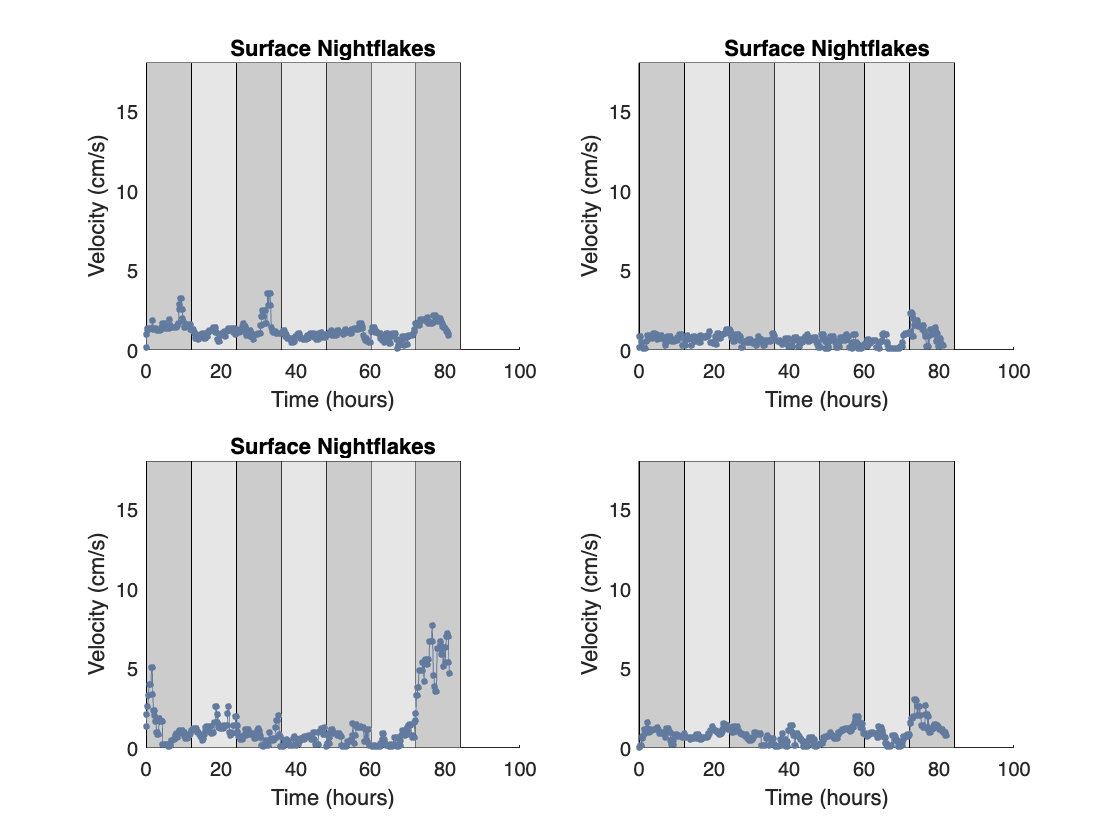

%indices of fmv data structure to plot
clear fmvidx;
clear k;
fmvidx = [9 10 11 12];

clf; 
%loop through idicies to generate plots
for k = 1:length(fmvidx)
    figure(1); title("Surface Nightflakes"); hold on; 
    
        subplot(2,2,k); hold on; ylim([0,18]);
        % created LD lines
        tmplightimes = fmv(fmvidx(k)).timfo.lighttimes-fmv(fmvidx(k)).timfo.timcont(1)';
        %create fill lines
         greydark = 0.8; greylight = 0.9;
       fill([tmplightimes(1)-tmplightimes(1) tmplightimes(1)-tmplightimes(1), tmplightimes(1) tmplightimes(1)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(2) tmplightimes(2) tmplightimes(3) tmplightimes(3)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(4) tmplightimes(4) tmplightimes(5) tmplightimes(5)], [0 18 18 0], [greylight greylight greylight])
       fill([tmplightimes(6) tmplightimes(6) tmplightimes(7) tmplightimes(7)], [0 18 18 0], [greylight greylight greylight])
       %ALWAYS DARK
       %ALL DARK
       fill([tmplightimes(1) tmplightimes(1), tmplightimes(2) tmplightimes(2)], [0 18 18 0],[0.8 0.8 0.8])
       fill([tmplightimes(3) tmplightimes(3) tmplightimes(4) tmplightimes(4)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(5) tmplightimes(5) tmplightimes(6) tmplightimes(6)], [0 18 18 0], [0.8 0.8 0.8])
       fill([tmplightimes(7) tmplightimes(7) tmplightimes(8) tmplightimes(8)], [0 18 18 0], [0.8 0.8 0.8])
       %plot
       plot([fmv(fmvidx(k)).timfo.timcont]-[fmv(fmvidx(k)).timfo.timcont(1)], (medfilt1([fmv(fmvidx(k)).ss.velmean], 7)), '.-', 'MarkerSize', 10, 'LineWidth', .2, 'Color', BlueSky);
       xlabel('Time (hours)');
       ylabel('Velocity (cm/s)'); 
       
    
end